**Creating the k-space grid and medium properties**

% % create the computational grid
% Nx = 1024;            % number of grid points in the x direction
% Ny = 16;            % number of grid points in the y direction
% Nz = 2048;            % number of grid points in the z direction
% dx = 0.1e-3;        % grid point spacing in the x direction [m]
% dy = 0.1e-3;        % grid point spacing in the y direction [m]
% dz = 0.1e-3;        % grid point spacing in the z direction [m]
% kgrid = kWaveGrid(Nx, dx, Ny, dy, Nz, dz);
% 
% % define the properties of the propagation medium
% medium.sound_speed = 1540;	% [m/s]
% medium.density = 1000;       % [kg/m^3]

% create the computational grid
Nx = 64;            % number of grid points in the x direction
Ny = 64;            % number of grid points in the y direction
Nz = 64;            % number of grid points in the z direction
dx = 0.1e-3;        % grid point spacing in the x direction [m]
dy = 0.1e-3;        % grid point spacing in the y direction [m]
dz = 0.1e-3;        % grid point spacing in the z direction [m]
kgrid = kWaveGrid(Nx, dx, Ny, dy, Nz, dz);

% define the properties of the propagation medium
medium.sound_speed = 1500 * ones(Nx, Ny, Nz);	% [m/s]
medium.sound_speed(1:Nx/2, :, :) = 1800;        % [m/s]
medium.density = 1000 * ones(Nx, Ny, Nz);       % [kg/m^3]
medium.density(:, Ny/4:end, :) = 1200;          % [kg/m^3]

**Defining the initial pressure distribution**

for i=1:50
    %ball_magnitude = 1;    % [Pa]
    %radius = randi([15e-6, 150e-6],1,1);
    ball_magnitude = 1;    % [Pa]
    radius = randi([5, 10],1,1);
    ball_x_pos = randi([0, Nx],1,1);        % [grid points]
    ball_y_pos = randi([0, Ny],1,1);        % [grid points]
    ball_z_pos = randi([0, Nz],1,1);        % [grid points]
    ball_i = ball_magnitude * makeBall(Nx, Ny, Nz, ball_x_pos, ball_y_pos, ball_z_pos, ball_radius);
    source.p0 = source.p0 + ball_i;
end



% create initial pressure distribution using makeBall
ball_magnitude = 10;    % [Pa]
ball_x_pos = 38;        % [grid points]
ball_y_pos = 32;        % [grid points]
ball_z_pos = 32;        % [grid points]
ball_radius = 5;        % [grid points]
ball_1 = ball_magnitude * makeBall(Nx, Ny, Nz, ball_x_pos, ball_y_pos, ball_z_pos, ball_radius);

ball_magnitude = 10;    % [Pa]
ball_x_pos = 20;        % [grid points]
ball_y_pos = 20;        % [grid points]
ball_z_pos = 20;        % [grid points]
ball_radius = 3;        % [grid points]
ball_2 = ball_magnitude * makeBall(Nx, Ny, Nz, ball_x_pos, ball_y_pos, ball_z_pos, ball_radius);

source.p0 = ball_1 + ball_2;

**Define the sensor mask**

% define a series of Cartesian points to collect the data
x = (-22:2:22) * dx;          % [m]
y = 22 * dy * ones(size(x));    % [m]
z = (-22:2:22) * dz;          % [m]
sensor.mask = [x; y; z];

**Running the simulation**

Running k-Wave simulation...
  start time: 06-Feb-2024 04:23:20
  reference sound speed: 1800m/s
  dt: 16.6667ns, t_end: 7.3833us, time steps: 444
  input grid size: 64 by 64 by 64 grid points (6.4 by 6.4 by 6.4mm)
  maximum supported frequency: 7.5MHz
  smoothing p0 distribution...
  casting variables to single type...


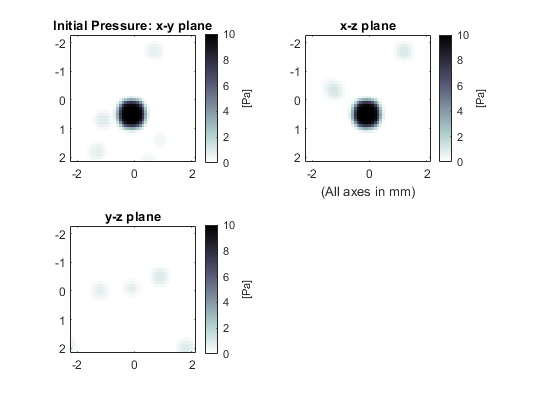

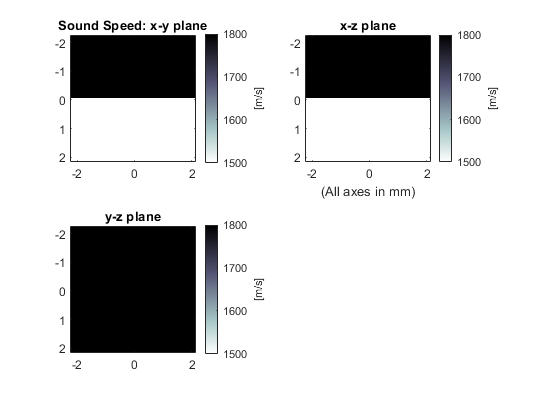

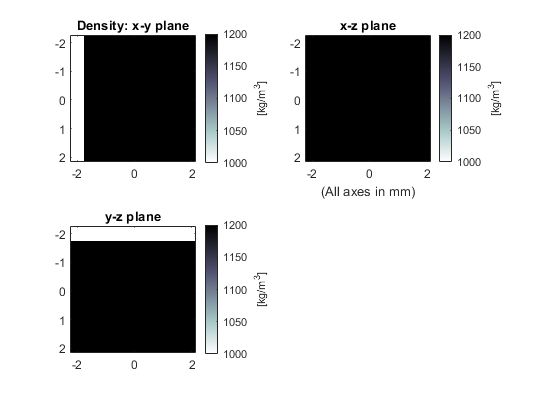

  precomputation completed in 1.4894s
  starting time loop...
  estimated simulation time 17.8932s...


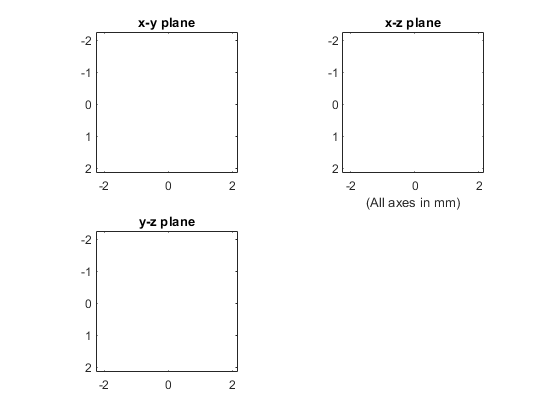

  simulation completed in 18.178s
  reordering Cartesian measurement data...
  total computation time 19.708s


% input arguments
input_args = {'PlotLayout', true, 'PlotPML', false, ...
    'DataCast', 'single', 'CartInterp', 'nearest'};

% run the simulation
sensor_data = kspaceFirstOrder3D(kgrid, medium, source, sensor, input_args{:});